# MATLAB Calling Tensorflow Model

Create by Fred Liu  2022/10/25

Reference Scoure: [davidwillingham](https://github.com/matlab-deep-learning/Image-Classification-in-MATLAB-Using-TensorFlow/commits?author=davidwillingham)

[https://github.com/matlab-deep-learning/Image-Classification-in-MATLAB-Using-TensorFlow](https://github.com/matlab-deep-learning/Image-Classification-in-MATLAB-Using-TensorFlow)

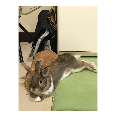

img = imread('image\r01.jpg');
figure,imshow(img)

Image Resize

imageHWSize = 480;
img2 = imresize(img, [imageHWSize, imageHWSize]);

調整通道順序(HWCN TO NHWC)

imgforTF = permute(img2, [4 1 2 3]); 
batch_size = int32(1); % Tensorflow require inputs to be converted to int32.

### Pyrun(在MATLAB使用Pythoncode)

pythonCode4 = [
    "from tensorflow.keras.applications import efficientnet_v2"
    "import numpy as np"
    "model = efficientnet_v2.EfficientNetV2L()"
    "X = np.asarray(imgforTF)"
    "X = efficientnet_v2.preprocess_input(X)"
    "Y = model.predict(X, batch_size)"
    "Y_decoded = efficientnet_v2.decode_predictions(Y)"
    "label = Y_decoded[0][0][1]; score = Y_decoded[0][0][2]"
    ];
[model, Y, label, score] = pyrun(pythonCode4, ["model", "Y", "label", "score"], "imgforTF", imgforTF, "batch_size", batch_size);

figure,imshow(img);
title(string(label));

### Pyrunfile(在MATLAB使用Python File)

[model3, Y3, label3, score3] = pyrunfile("TensorFlow_using_DLmodel.py", ["model3","Y3","label3","score3"])

wood_rabbit
0.6305062


model3 = sys:1: UserWarning: `Model.state_updates` will be removed in a future version. This property should not be used in TensorFlow 2.0, as `updates` are applied automatically.
sys:1: UserWarning: `layer.updates` will be removed in a future version. This property should not be used in TensorFlow 2.0, as `updates` are applied automatically.
  Python Functional with properties:

       activity_regularizer: [1×1 py.NoneType]
              compute_dtype: [1×7 py.str]
        distribute_strategy: [1×1 py.tensorflow.python.distribute.distribute_lib._DefaultDistributionStrategy]
                      dtype: [1×7 py.str]
               dtype_policy: [1×1 py.keras.mixed_precision.policy.Policy]
                    dynamic: 0
              inbound_nodes: [1×0 py.list]
                      input: [1×1 py.keras.engine.keras_tensor.KerasTensor]
                 input_mask: [1×1 py.NoneType]
          

Y3 =   Python ndarray:

  Columns 1 through 999

    0.0002    0.0001    0.0002    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0002    0.0003    0.0002    0.0002    0.0001    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0002    0.0001    0.0001    0.0002    0.0002    0.0001    0.0001    0.0002    0.0001    0.0002    0.0002    0.0001    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0002    0.0003    0.0002    0.0001    0.0002    0.0003    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0006    0.0002    0.0002    0.0003    0.0002    0.0003    0.0001    0.0003    0.0002    0.00

label3 =   Python str with no properties.

    wood_rabbit


score3 =   Python float32:

    0.6305

    Use details function to view the properties of the Python object.

    Use single function to convert to a MATLAB array.


## MATLAB Live Task for Python Package

可以在Live Script中嵌入的Live Task

Reference Scoure: [jpkmw](https://github.com/mathworks/MATLAB-Live-Task-for-Python/commits?author=jpkmw)

[https://github.com/mathworks/MATLAB-Live-Task-for-Python](https://github.com/mathworks/MATLAB-Live-Task-for-Python)

使用方式：

先去以上連結下載安裝包

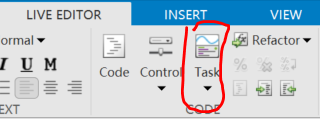

選擇Run Python Code

% Running Python statements from Live Task
pythonCode10 = [
    "from tensorflow.keras.applications import efficientnet_v2"
    "import numpy as np"
    "model2 = efficientnet_v2.EfficientNetV2L()"
    "X = np.asarray(imgforTF)"
    "X = efficientnet_v2.preprocess_input(X)"
    "Y2 = model2.predict(X, batch_size)"
    "Y_decoded = efficientnet_v2.decode_predictions(Y2)"
    "label2 = Y_decoded[0][0][1];"
    "score2 = Y_decoded[0][0][2]"
    ];
[model2, Y2, label2, score2] = pyrun(pythonCode10, ["model2", "Y2", "label2", "score2"], "imgforTF", imgforTF, "batch_size", batch_size);